# Exercize 1

clear; close all; clc;

Number of Agents in the Network 

N = 7;

Number of possible Topologies of the Network

R = 4;

Control Gain (the dynamics simulation will be performed with 3 different control gains in order to verify the differences)

k1 = 0.5;
k2 = 0.8;
k3 = 1.7;
K = [k1 k2 k3];

Sampling Time: empirical rule suggests $0<T_s <\frac{1}{10\cdot \lambda_{\max } }\;$where $\lambda_{\max }$is the largest eigenvalue of the combined Laplacians.

Ts = 0.1; 

Final Time

Tend = 9;

Time Line

kend = ceil(Tend/Ts)-1;
Time = 0:Ts:kend*Ts;

### Switching Sequence

The switching sequence $\sigma \left(t\right)$ is a signal that determines which Laplacian matrix is active at time $t$.

                                            
$$\sigma :\Re_+ \to \left\lbrace 1,\ldotp \ldotp \ldotp ,R\right\rbrace$$


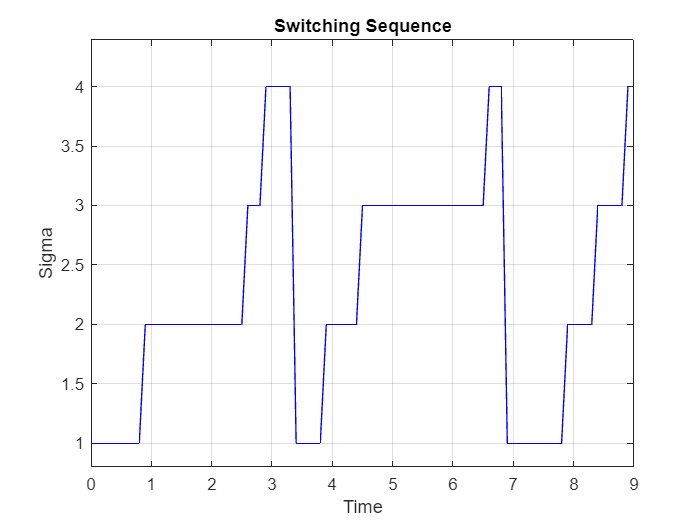

Tswitch=ceil([1 2.7 3 3.5 4 4.6 6.7 7 8 8.5 9]/Ts);  
Sigma = [];
Sigma(1) = 1;
j = 1;

for i=2:kend+1
    Sigma(i)=Sigma(i-1);
    if i==Tswitch(j)
        Sigma(i)=Sigma(i)+1;
        if Sigma(i)==5
            Sigma(i)=1;
        end
        j=j+1;
    end
end

figure(1)
plot(Time, Sigma, 'b');
grid
ylabel('Sigma');
xlabel('Time');
axis([0 Tend 0.8 4.4]);
title('Switching Sequence')

### Topologies of the Network

First (Path Graph)

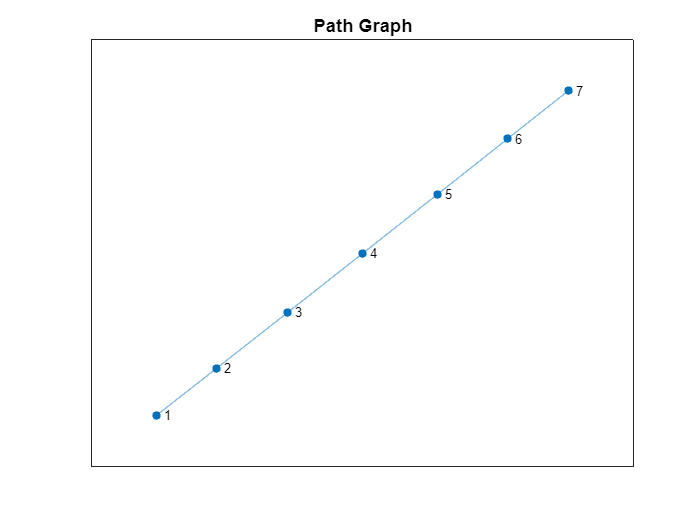

% Adjacency matrix
A1 = [0 1 0 0 0 0 0;
      1 0 1 0 0 0 0;
      0 1 0 1 0 0 0;
      0 0 1 0 1 0 0;
      0 0 0 1 0 1 0;
      0 0 0 0 1 0 1;
      0 0 0 0 0 1 0];
G1 = graph(A1);
figure(2);
plot(G1,'Layout','force')
title('Path Graph');

Second (Star Graph)

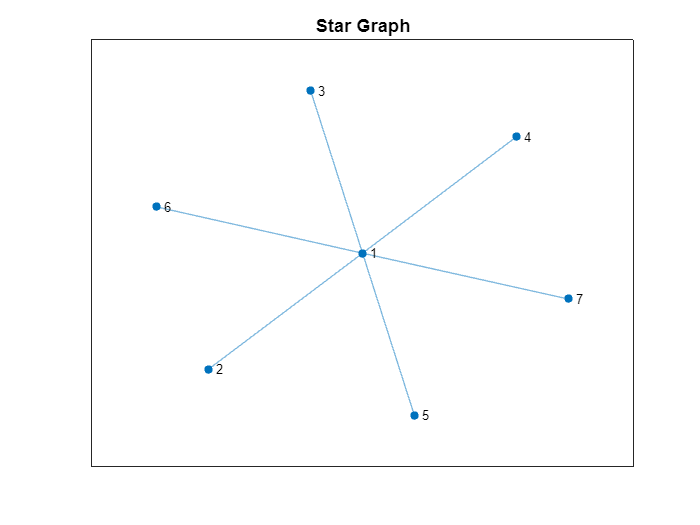

% Adjacency matrix
A2 = [0 1 1 1 1 1 1;
      1 0 0 0 0 0 0;
      1 0 0 0 0 0 0;
      1 0 0 0 0 0 0;
      1 0 0 0 0 0 0;
      1 0 0 0 0 0 0;
      1 0 0 0 0 0 0];
G2 = graph(A2);
figure(3);
plot(G2,'Layout','force')
title('Star Graph');

Third (Ring Graph)

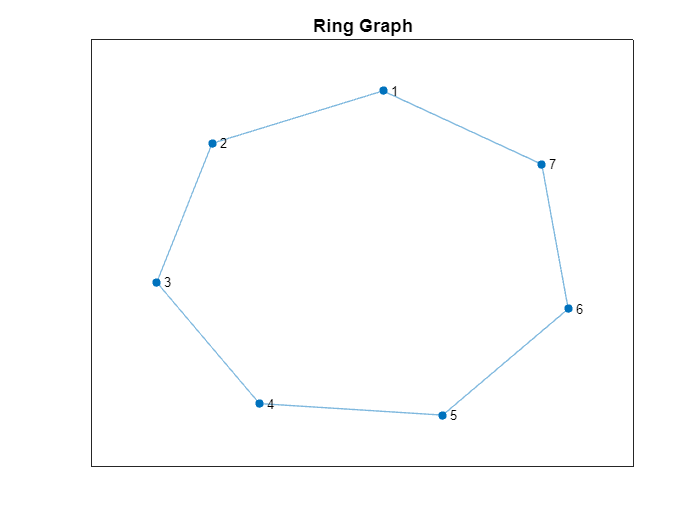

% Adjacency matrix
A3 = [0 1 0 0 0 0 1;
      1 0 1 0 0 0 0;
      0 1 0 1 0 0 0;
      0 0 1 0 1 0 0;
      0 0 0 1 0 1 0;
      0 0 0 0 1 0 1;
      1 0 0 0 0 1 0];
G3 = graph(A3);
figure(4);
plot(G3,'Layout','force')
title('Ring Graph');

Fourth (Random Connected Graph)

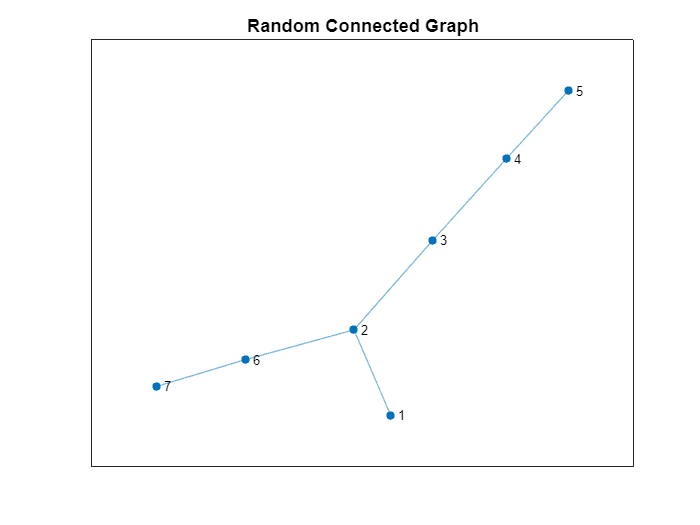

% Adjacency matrix
A4 = [0 1 0 0 0 0 0;
      1 0 1 0 0 1 0;
      0 1 0 1 0 0 0;
      0 0 1 0 1 0 0;
      0 0 0 1 0 0 0;
      0 1 0 0 0 0 1;
      0 0 0 0 0 1 0];
G4 = graph(A4);
figure(5);
plot(G4,'Layout','force')
title('Random Connected Graph');

#### Laplacian Matrices 


$$L:=D-A$$


where $D$ is a Diagonal Degree Matrix which represents the number of entering edges of each  node

                    $D=\textrm{diag}\left(d_1 ,\ldotp \ldotp \ldotp ,d_N \right)\;$        where         $d_i =\sum_{j=0}^N a_{\textrm{ij}} \;$(*IN-DEGREE*)

We can say that

1) $L$ has a non-negative diagonal

2) The remaining part of $L$ is non-positive (beacase $A$ is a non-negative matrix)

L1 = diag(sum(A1))-A1;
L2 = diag(sum(A2))-A2;
L3 = diag(sum(A3))-A3;
L4 = diag(sum(A4))-A4;

The **Control Law** for each Agent of the Network


$$u_{i\;} \left(t\right)=-k\;\sum_{j\in N_i^{\left(\sigma \left(t\right)\right)} } \left\lbrack x_i \left(t\right)-x_j \left(t\right)\right\rbrack$$


where $N_i^{\left(\sigma \left(t\right)\right)}$ denotes the set of neighbors of agent $i$ in the topology active at time $t$.

The **Global Dynamics** (vector form) is given by

$\dot{x} \left(t\right)=-k\;L^{\left(\sigma \left(t\right)\right)} x\left(t\right)\;$where $\;L^{\left(\sigma \left(t\right)\right)}$ is the Laplacian matrix of the active topology at time $t$.

This system is a **Hybrid System **because there is continuity for $\dot{x} \left(t\right)$ and, because of $L^{\left(\sigma \left(t\right)\right)}$, we also have the discrete term.

### ***Simulation***

Initial state

x0 = [2 -1 0.75 1.1 0.4 0 1.6]';

Since we have a **continuous time **dynamics, we have the following dynamic (discretized version):


$$x\left({\mathrm{kT}}_s \right)=e^{-{k\cdot L}^{\left(\sigma \left(t\right)\right)} T_s } \;x\left(\left(k-1\right)T_s \right)\;$$


About the **consensus value**, it is the average of the initial state because the graphs of the Network are undirected


$$\bar{x} =\frac{1}{N}\sum_{i=0}^N x_{0,i}$$


bar_x = mean(x0)

bar_x = 0.6929

Loop for the simulation

for k = 1:length(K)
    X = [];
    X(1,:) = x0;

    for i=2:kend+1
        switch Sigma(i)
            case 1
                X(i,:) = expm(-K(k)*L1*Ts)*X(i-1,:)';
            case 2
                X(i,:) = expm(-K(k)*L2*Ts)*X(i-1,:)';
            case 3
                X(i,:) = expm(-K(k)*L3*Ts)*X(i-1,:)';
            case 4
                X(i,:) = expm(-K(k)*L4*Ts)*X(i-1,:)';
        end
    end


            Plot

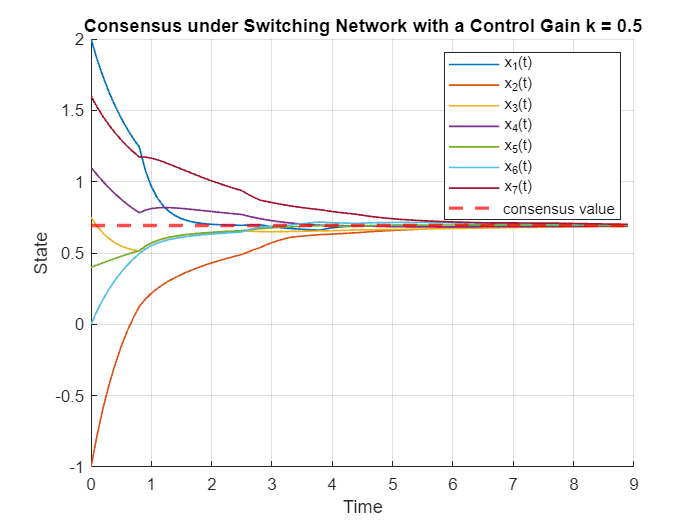

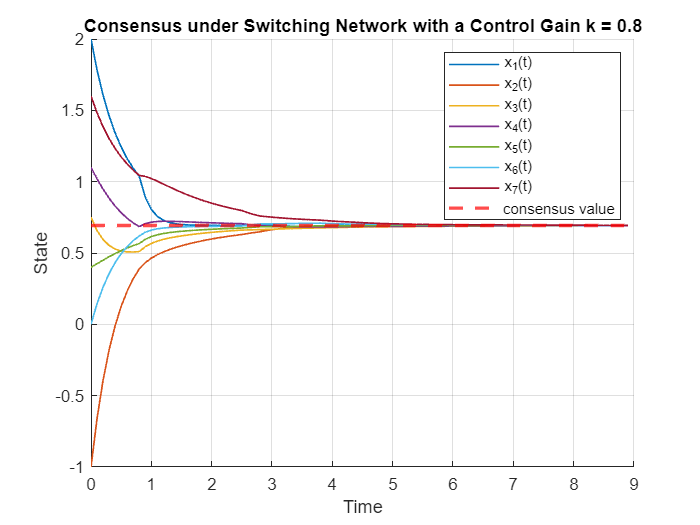

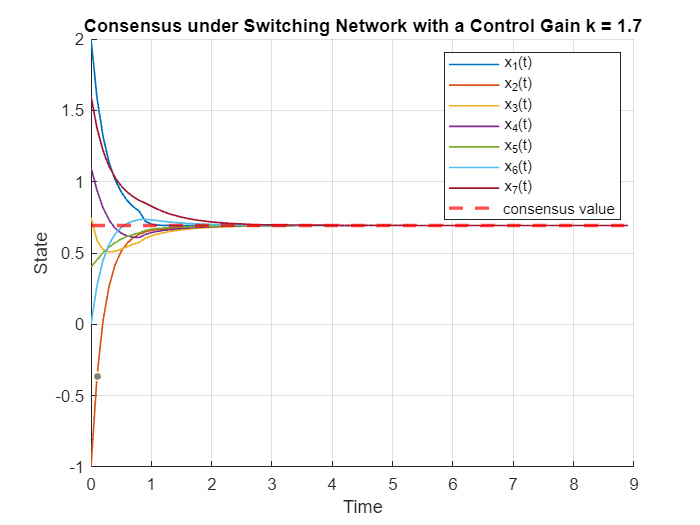

    colors = lines(N);
    figure;
    hold on;
    for agent = 1:N
        plot(Time, X(:, agent), 'Color', colors(agent,:), 'LineWidth', 1);
    end
    
    yline(bar_x, '--r','LineWidth', 2);
    hold off
    xlabel('Time')
    ylabel('State')
    legend('x_1(t)','x_2(t)','x_3(t)','x_4(t)','x_5(t)','x_6(t)','x_7(t)','consensus value')
    title(['Consensus under Switching Network with a Control Gain k = ', num2str(K(k))])
    grid
end

### Plot Description

- ***First plot*** ($k=0\ldotp 5$): the convergence to the consensus value is slow (Convergence Time is about $7\;s$); in fact, some agents take longer to approach the common value. Choosing $k=0\ldotp 5$ is good to avoid oscillations, but time inefficient.

- ***Second plot*** ($k=0\ldotp 8$): the convergence speed is visibly improved compared to before (Convergence Time is about $5\;s$); it has a higher gain; it improves the consensus speed without introducing instability.

- ***Third plot*** ($k=1\ldotp 7$): the system converges very quickly to the consensus value (Convergence Time is about $2\;s$); there is no visible oscillation, in fact the convergence is stable and clear. The choice of $k=1\ldotp 7$ is great for speed, but may be at risk of instability in systems with delays or noise.

## Conclusions

- All agents reached a common consensus value, equal to the average of the initial state, thanks to the symmetry and connection of the topologies involved.

- Increasing the gain $k$ accelerates convergence to consensus.